target = [42.2932850000000	-71.2643730000000];
current = [42.293252 -71.264429];
figure
hold on
plot(target(1),target(2),'kx','MarkerSize',60)
plot(current(1),current(2),'bx','MarkerSize',30)
leftcircle = [-78.3172   -0.1904];
r = 139.9943

r = 139.9943

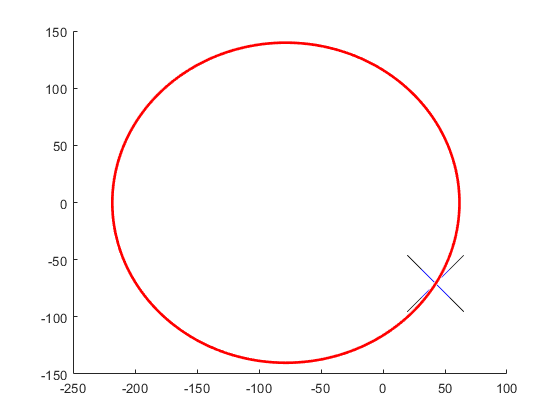

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


viscircles(leftcircle(1,:),r)

New_Rover_Locations = [-218.3115   -0.1904]

New_Rover_Locations = -61.6000

plot(New_Rover_Locations(1),New_Rover_Locations(2),'x','MarkerSize',30)

Index exceeds the number of array elements (1).

hold off


x = 2

y = 3

x_int = 1.9476

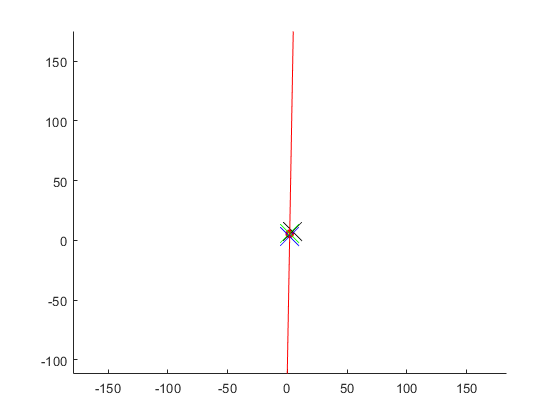

m = 57.2900

c = -111.5799

circle_center =     2.0433    5.4784


radius = 2.4787

ans = 8.8818e-16

circle_center =     2.0433    5.4784


radius = 2.4787

roverLocation = [2 3];
targetWaypoint = [4 7];
roverBearing = 91;
[circle_center,radius] = findCircle(roverLocation, targetWaypoint, roverBearing)

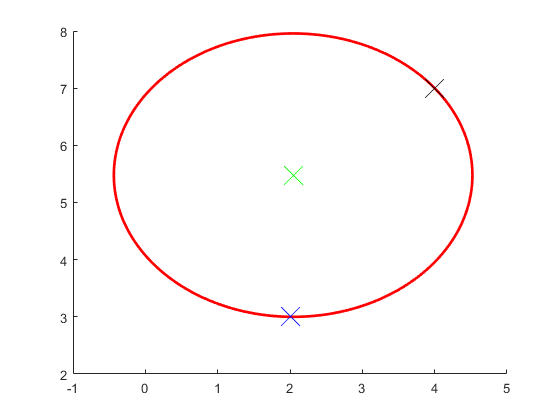

hold on
plot(circle_center(1),circle_center(2),'gx',"MarkerSize",20)
hold off

function [circle_center, radius] = findCircle(roverLocation, targetWaypoint, roverBearing)


%% find the equation of the circle given line and two points

% find the equation of the line that i
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[m, c] = find_line(roverLocation, roverBearing)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%y =  mx +  c
%ax + by +  d = 0
%mx - y +   c = 0
a = m;
b = -1;
d = c;

% equation of a circle
% x2+y2+2gx+2fy+c=0 (-g,-f) is the center
x1 = roverLocation(1); y1 = roverLocation(2);
x2 = targetWaypoint(1); y2 = targetWaypoint(2);
syms g f c
eqn1 = x1^2 + y1^2 + 2*g*x1 + 2*f*y1 + c == 0;
eqn2 = x2^2 + y2^2 + 2*g*x2 + 2*f*y2 + c == 0;

% substitute g and f into the equation of the line
eqn3 = a*-g + b*-f + d == 0;

% solving the three equations
sol = solve([eqn1, eqn2, eqn3], [g, f, c]);
G = sol.g;
F = sol.f;
C = sol.c;

% assigning the circle center
circle_center = double([-G, -F])

% finding the radius
radius = norm(circle_center - roverLocation)

% sanity check to make sure its passing throught the points
% this should be 0
radius - norm(circle_center - targetWaypoint)

%plotting
figure
hold on
viscircles(circle_center,radius);
plot(targetWaypoint(1),targetWaypoint(2),'kx','MarkerSize',20)
plot(roverLocation(1),roverLocation(2),'bx','MarkerSize',20)
hold off
end

function [m, b] = find_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1)
    y = roverPosition(2)
    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        omega = mod(roverBearing+90, 90);
        omega = 90 - omega
        a = abs(y*tand(omega));
        x_int = a+x;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        omega = mod(roverBearing+90, 90);
        a = abs(y*tand(omega));
        x_int = x-a
    end
    m = (y-0)/(x-x_int);
    b = y-m*x;
    
 hold on
x= linspace(0,5, 10); % Adapt n for resolution of graph
y= m*x + b;

plot(x, y, 'r')
axis equal

end